# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       computeCost.m           ex1_companion.mlx       featureNormalize.m      gradientDescentMulti.m  plotData.m              warmUpExercise.asv      
..                      computeCostMulti.m      ex1data1.txt            gradientDescent.asv     normalEqn.m             submit.m                warmUpExercise.m        
computeCost.asv         ex1.mlx                 ex1data2.txt            gradientDescent.m       plotData.asv            token.mat               warmUpExercise.mlx      



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

You should see output similar to the following:

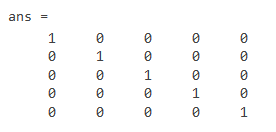

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

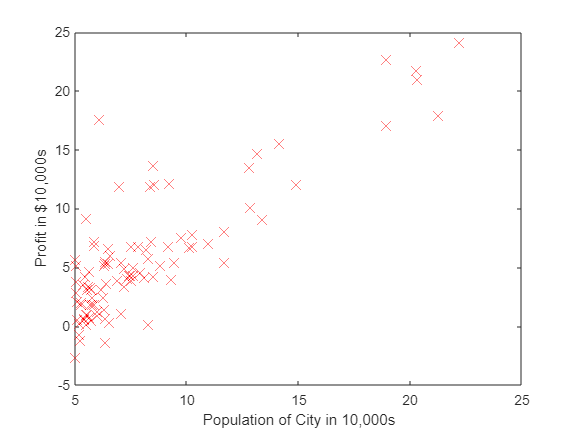

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

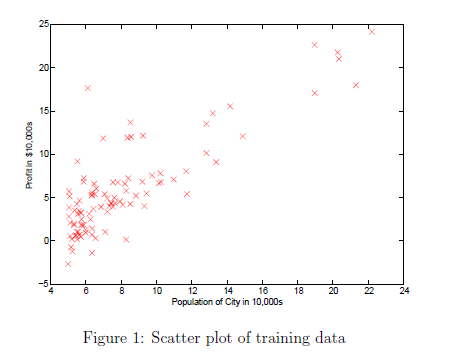

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

J = 6.5592e+10

ans = 6.5592e+10

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

J = 6.4073e+10

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

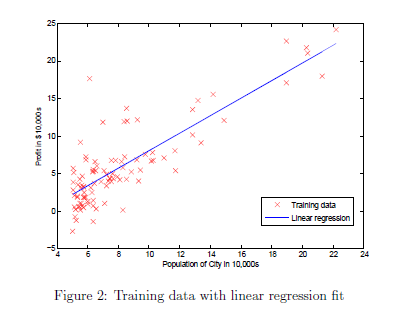    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

J = 6.3390e+04

J = 5.5810e+04

J = 5.5524e+04

J = 5.5468e+04

J = 5.5420e+04

J = 5.5372e+04

J = 5.5324e+04

J = 5.5277e+04

J = 5.5229e+04

J = 5.5182e+04

J = 5.5135e+04

J = 5.5088e+04

J = 5.5042e+04

J = 5.4995e+04

J = 5.4949e+04

J = 5.4902e+04

J = 5.4856e+04

J = 5.4811e+04

J = 5.4765e+04

J = 5.4719e+04

J = 5.4674e+04

J = 5.4629e+04

J = 5.4584e+04

J = 5.4539e+04

J = 5.4494e+04

J = 5.4450e+04

J = 5.4405e+04

J = 5.4361e+04

J = 5.4317e+04

J = 5.4273e+04

J = 5.4229e+04

J = 5.4186e+04

J = 5.4142e+04

J = 5.4099e+04

J = 5.4056e+04

J = 5.4013e+04

J = 5.3970e+04

J = 5.3927e+04

J = 5.3885e+04

J = 5.3842e+04

J = 5.3800e+04

J = 5.3758e+04

J = 5.3716e+04

J = 5.3674e+04

J = 5.3633e+04

J = 5.3591e+04

J = 5.3550e+04

J = 5.3509e+04

J = 5.3468e+04

J = 5.3427e+04

J = 5.3386e+04

J = 5.3346e+04

J = 5.3305e+04

J = 5.3265e+04

J = 5.3225e+04

J = 5.3185e+04

J = 5.3145e+04

J = 5.3105e+04

J = 5.3066e+04

J = 5.3026e+04

J = 5.2987e+04

J = 5.2948e+04

J = 5.2909e+04

J = 5.2870e+04

J = 5.2832e+04

J = 5.2793e+04

J = 5.2755e+04

J = 5.2716e+04

J = 5.2678e+04

J = 5.2640e+04

J = 5.2602e+04

J = 5.2564e+04

J = 5.2527e+04

J = 5.2489e+04

J = 5.2452e+04

J = 5.2415e+04

J = 5.2378e+04

J = 5.2341e+04

J = 5.2304e+04

J = 5.2267e+04

J = 5.2231e+04

J = 5.2194e+04

J = 5.2158e+04

J = 5.2122e+04

J = 5.2086e+04

J = 5.2050e+04

J = 5.2014e+04

J = 5.1979e+04

J = 5.1943e+04

J = 5.1908e+04

J = 5.1873e+04

J = 5.1837e+04

J = 5.1803e+04

J = 5.1768e+04

J = 5.1733e+04

J = 5.1698e+04

J = 5.1664e+04

J = 5.1629e+04

J = 5.1595e+04

J = 5.1561e+04

J = 5.1527e+04

J = 5.1493e+04

J = 5.1459e+04

J = 5.1426e+04

J = 5.1392e+04

J = 5.1359e+04

J = 5.1326e+04

J = 5.1293e+04

J = 5.1260e+04

J = 5.1227e+04

J = 5.1194e+04

J = 5.1161e+04

J = 5.1129e+04

J = 5.1096e+04

J = 5.1064e+04

J = 5.1032e+04

J = 5.1000e+04

J = 5.0968e+04

J = 5.0936e+04

J = 5.0904e+04

J = 5.0872e+04

J = 5.0841e+04

J = 5.0809e+04

J = 5.0778e+04

J = 5.0747e+04

J = 5.0716e+04

J = 5.0685e+04

J = 5.0654e+04

J = 5.0623e+04

J = 5.0593e+04

J = 5.0562e+04

J = 5.0532e+04

J = 5.0502e+04

J = 5.0471e+04

J = 5.0441e+04

J = 5.0411e+04

J = 5.0382e+04

J = 5.0352e+04

J = 5.0322e+04

J = 5.0293e+04

J = 5.0263e+04

J = 5.0234e+04

J = 5.0205e+04

J = 5.0176e+04

J = 5.0147e+04

J = 5.0118e+04

J = 5.0089e+04

J = 5.0060e+04

J = 5.0032e+04

J = 5.0003e+04

J = 4.9975e+04

J = 4.9947e+04

J = 4.9918e+04

J = 4.9890e+04

J = 4.9862e+04

J = 4.9834e+04

J = 4.9807e+04

J = 4.9779e+04

J = 4.9751e+04

J = 4.9724e+04

J = 4.9697e+04

J = 4.9669e+04

J = 4.9642e+04

J = 4.9615e+04

J = 4.9588e+04

J = 4.9561e+04

J = 4.9534e+04

J = 4.9508e+04

J = 4.9481e+04

J = 4.9455e+04

J = 4.9428e+04

J = 4.9402e+04

J = 4.9376e+04

J = 4.9350e+04

J = 4.9323e+04

J = 4.9298e+04

J = 4.9272e+04

J = 4.9246e+04

J = 4.9220e+04

J = 4.9195e+04

J = 4.9169e+04

J = 4.9144e+04

J = 4.9119e+04

J = 4.9093e+04

J = 4.9068e+04

J = 4.9043e+04

J = 4.9018e+04

J = 4.8994e+04

J = 4.8969e+04

J = 4.8944e+04

J = 4.8920e+04

J = 4.8895e+04

J = 4.8871e+04

J = 4.8846e+04

J = 4.8822e+04

J = 4.8798e+04

J = 4.8774e+04

J = 4.8750e+04

J = 4.8726e+04

J = 4.8702e+04

J = 4.8679e+04

J = 4.8655e+04

J = 4.8632e+04

J = 4.8608e+04

J = 4.8585e+04

J = 4.8562e+04

J = 4.8538e+04

J = 4.8515e+04

J = 4.8492e+04

J = 4.8469e+04

J = 4.8446e+04

J = 4.8424e+04

J = 4.8401e+04

J = 4.8378e+04

J = 4.8356e+04

J = 4.8333e+04

J = 4.8311e+04

J = 4.8289e+04

J = 4.8267e+04

J = 4.8244e+04

J = 4.8222e+04

J = 4.8200e+04

J = 4.8178e+04

J = 4.8157e+04

J = 4.8135e+04

J = 4.8113e+04

J = 4.8092e+04

J = 4.8070e+04

J = 4.8049e+04

J = 4.8027e+04

J = 4.8006e+04

J = 4.7985e+04

J = 4.7964e+04

J = 4.7943e+04

J = 4.7922e+04

J = 4.7901e+04

J = 4.7880e+04

J = 4.7859e+04

J = 4.7839e+04

J = 4.7818e+04

J = 4.7798e+04

J = 4.7777e+04

J = 4.7757e+04

J = 4.7737e+04

J = 4.7716e+04

J = 4.7696e+04

J = 4.7676e+04

J = 4.7656e+04

J = 4.7636e+04

J = 4.7616e+04

J = 4.7597e+04

J = 4.7577e+04

J = 4.7557e+04

J = 4.7538e+04

J = 4.7518e+04

J = 4.7499e+04

J = 4.7479e+04

J = 4.7460e+04

J = 4.7441e+04

J = 4.7422e+04

J = 4.7403e+04

J = 4.7384e+04

J = 4.7365e+04

J = 4.7346e+04

J = 4.7327e+04

J = 4.7308e+04

J = 4.7290e+04

J = 4.7271e+04

J = 4.7252e+04

J = 4.7234e+04

J = 4.7216e+04

J = 4.7197e+04

J = 4.7179e+04

J = 4.7161e+04

J = 4.7143e+04

J = 4.7125e+04

J = 4.7107e+04

J = 4.7089e+04

J = 4.7071e+04

J = 4.7053e+04

J = 4.7035e+04

J = 4.7017e+04

J = 4.7000e+04

J = 4.6982e+04

J = 4.6965e+04

J = 4.6947e+04

J = 4.6930e+04

J = 4.6913e+04

J = 4.6895e+04

J = 4.6878e+04

J = 4.6861e+04

J = 4.6844e+04

J = 4.6827e+04

J = 4.6810e+04

J = 4.6793e+04

J = 4.6776e+04

J = 4.6760e+04

J = 4.6743e+04

J = 4.6726e+04

J = 4.6710e+04

J = 4.6693e+04

J = 4.6677e+04

J = 4.6660e+04

J = 4.6644e+04

J = 4.6628e+04

J = 4.6611e+04

J = 4.6595e+04

J = 4.6579e+04

J = 4.6563e+04

J = 4.6547e+04

J = 4.6531e+04

J = 4.6515e+04

J = 4.6500e+04

J = 4.6484e+04

J = 4.6468e+04

J = 4.6452e+04

J = 4.6437e+04

J = 4.6421e+04

J = 4.6406e+04

J = 4.6390e+04

J = 4.6375e+04

J = 4.6360e+04

J = 4.6344e+04

J = 4.6329e+04

J = 4.6314e+04

J = 4.6299e+04

J = 4.6284e+04

J = 4.6269e+04

J = 4.6254e+04

J = 4.6239e+04

J = 4.6224e+04

J = 4.6210e+04

J = 4.6195e+04

J = 4.6180e+04

J = 4.6166e+04

J = 4.6151e+04

J = 4.6137e+04

J = 4.6122e+04

J = 4.6108e+04

J = 4.6093e+04

J = 4.6079e+04

J = 4.6065e+04

J = 4.6051e+04

J = 4.6036e+04

J = 4.6022e+04

J = 4.6008e+04

J = 4.5994e+04

J = 4.5980e+04

J = 4.5966e+04

J = 4.5953e+04

J = 4.5939e+04

J = 4.5925e+04

J = 4.5911e+04

J = 4.5898e+04

J = 4.5884e+04

J = 4.5871e+04

J = 4.5857e+04

J = 4.5844e+04

J = 4.5830e+04

J = 4.5817e+04

J = 4.5804e+04

J = 4.5790e+04

J = 4.5777e+04

J = 4.5764e+04

J = 4.5751e+04

J = 4.5738e+04

J = 4.5725e+04

J = 4.5712e+04

J = 4.5699e+04

J = 4.5686e+04

J = 4.5673e+04

J = 4.5660e+04

J = 4.5648e+04

J = 4.5635e+04

J = 4.5622e+04

J = 4.5610e+04

J = 4.5597e+04

J = 4.5585e+04

J = 4.5572e+04

J = 4.5560e+04

J = 4.5547e+04

J = 4.5535e+04

J = 4.5523e+04

J = 4.5511e+04

J = 4.5498e+04

J = 4.5486e+04

J = 4.5474e+04

J = 4.5462e+04

J = 4.5450e+04

J = 4.5438e+04

J = 4.5426e+04

J = 4.5414e+04

J = 4.5402e+04

J = 4.5391e+04

J = 4.5379e+04

J = 4.5367e+04

J = 4.5355e+04

J = 4.5344e+04

J = 4.5332e+04

J = 4.5321e+04

J = 4.5309e+04

J = 4.5298e+04

J = 4.5286e+04

J = 4.5275e+04

J = 4.5263e+04

J = 4.5252e+04

J = 4.5241e+04

J = 4.5230e+04

J = 4.5218e+04

J = 4.5207e+04

J = 4.5196e+04

J = 4.5185e+04

J = 4.5174e+04

J = 4.5163e+04

J = 4.5152e+04

J = 4.5141e+04

J = 4.5130e+04

J = 4.5120e+04

J = 4.5109e+04

J = 4.5098e+04

J = 4.5087e+04

J = 4.5077e+04

J = 4.5066e+04

J = 4.5055e+04

J = 4.5045e+04

J = 4.5034e+04

J = 4.5024e+04

J = 4.5013e+04

J = 4.5003e+04

J = 4.4993e+04

J = 4.4982e+04

J = 4.4972e+04

J = 4.4962e+04

J = 4.4951e+04

J = 4.4941e+04

J = 4.4931e+04

J = 4.4921e+04

J = 4.4911e+04

J = 4.4901e+04

J = 4.4891e+04

J = 4.4881e+04

J = 4.4871e+04

J = 4.4861e+04

J = 4.4851e+04

J = 4.4841e+04

J = 4.4832e+04

J = 4.4822e+04

J = 4.4812e+04

J = 4.4802e+04

J = 4.4793e+04

J = 4.4783e+04

J = 4.4774e+04

J = 4.4764e+04

J = 4.4755e+04

J = 4.4745e+04

J = 4.4736e+04

J = 4.4726e+04

J = 4.4717e+04

J = 4.4708e+04

J = 4.4698e+04

J = 4.4689e+04

J = 4.4680e+04

J = 4.4671e+04

J = 4.4661e+04

J = 4.4652e+04

J = 4.4643e+04

J = 4.4634e+04

J = 4.4625e+04

J = 4.4616e+04

J = 4.4607e+04

J = 4.4598e+04

J = 4.4589e+04

J = 4.4580e+04

J = 4.4571e+04

J = 4.4563e+04

J = 4.4554e+04

J = 4.4545e+04

J = 4.4536e+04

J = 4.4528e+04

J = 4.4519e+04

J = 4.4510e+04

J = 4.4502e+04

J = 4.4493e+04

J = 4.4485e+04

J = 4.4476e+04

J = 4.4468e+04

J = 4.4459e+04

J = 4.4451e+04

J = 4.4442e+04

J = 4.4434e+04

J = 4.4426e+04

J = 4.4418e+04

J = 4.4409e+04

J = 4.4401e+04

J = 4.4393e+04

J = 4.4385e+04

J = 4.4376e+04

J = 4.4368e+04

J = 4.4360e+04

J = 4.4352e+04

J = 4.4344e+04

J = 4.4336e+04

J = 4.4328e+04

J = 4.4320e+04

J = 4.4312e+04

J = 4.4305e+04

J = 4.4297e+04

J = 4.4289e+04

J = 4.4281e+04

J = 4.4273e+04

J = 4.4266e+04

J = 4.4258e+04

J = 4.4250e+04

J = 4.4242e+04

J = 4.4235e+04

J = 4.4227e+04

J = 4.4220e+04

J = 4.4212e+04

J = 4.4205e+04

J = 4.4197e+04

J = 4.4190e+04

J = 4.4182e+04

J = 4.4175e+04

J = 4.4167e+04

J = 4.4160e+04

J = 4.4153e+04

J = 4.4145e+04

J = 4.4138e+04

J = 4.4131e+04

J = 4.4124e+04

J = 4.4116e+04

J = 4.4109e+04

J = 4.4102e+04

J = 4.4095e+04

J = 4.4088e+04

J = 4.4081e+04

J = 4.4074e+04

J = 4.4067e+04

J = 4.4060e+04

J = 4.4053e+04

J = 4.4046e+04

J = 4.4039e+04

J = 4.4032e+04

J = 4.4025e+04

J = 4.4018e+04

J = 4.4011e+04

J = 4.4005e+04

J = 4.3998e+04

J = 4.3991e+04

J = 4.3984e+04

J = 4.3978e+04

J = 4.3971e+04

J = 4.3964e+04

J = 4.3958e+04

J = 4.3951e+04

J = 4.3945e+04

J = 4.3938e+04

J = 4.3931e+04

J = 4.3925e+04

J = 4.3918e+04

J = 4.3912e+04

J = 4.3906e+04

J = 4.3899e+04

J = 4.3893e+04

J = 4.3886e+04

J = 4.3880e+04

J = 4.3874e+04

J = 4.3867e+04

J = 4.3861e+04

J = 4.3855e+04

J = 4.3849e+04

J = 4.3842e+04

J = 4.3836e+04

J = 4.3830e+04

J = 4.3824e+04

J = 4.3818e+04

J = 4.3812e+04

J = 4.3806e+04

J = 4.3800e+04

J = 4.3793e+04

J = 4.3787e+04

J = 4.3781e+04

J = 4.3775e+04

J = 4.3770e+04

J = 4.3764e+04

J = 4.3758e+04

J = 4.3752e+04

J = 4.3746e+04

J = 4.3740e+04

J = 4.3734e+04

J = 4.3728e+04

J = 4.3723e+04

J = 4.3717e+04

J = 4.3711e+04

J = 4.3706e+04

J = 4.3700e+04

J = 4.3694e+04

J = 4.3688e+04

J = 4.3683e+04

J = 4.3677e+04

J = 4.3672e+04

J = 4.3666e+04

J = 4.3660e+04

J = 4.3655e+04

J = 4.3649e+04

J = 4.3644e+04

J = 4.3638e+04

J = 4.3633e+04

J = 4.3628e+04

J = 4.3622e+04

J = 4.3617e+04

J = 4.3611e+04

J = 4.3606e+04

J = 4.3601e+04

J = 4.3595e+04

J = 4.3590e+04

J = 4.3585e+04

J = 4.3580e+04

J = 4.3574e+04

J = 4.3569e+04

J = 4.3564e+04

J = 4.3559e+04

J = 4.3554e+04

J = 4.3548e+04

J = 4.3543e+04

J = 4.3538e+04

J = 4.3533e+04

J = 4.3528e+04

J = 4.3523e+04

J = 4.3518e+04

J = 4.3513e+04

J = 4.3508e+04

J = 4.3503e+04

J = 4.3498e+04

J = 4.3493e+04

J = 4.3488e+04

J = 4.3483e+04

J = 4.3478e+04

J = 4.3473e+04

J = 4.3468e+04

J = 4.3464e+04

J = 4.3459e+04

J = 4.3454e+04

J = 4.3449e+04

J = 4.3444e+04

J = 4.3440e+04

J = 4.3435e+04

J = 4.3430e+04

J = 4.3425e+04

J = 4.3421e+04

J = 4.3416e+04

J = 4.3411e+04

J = 4.3407e+04

J = 4.3402e+04

J = 4.3398e+04

J = 4.3393e+04

J = 4.3388e+04

J = 4.3384e+04

J = 4.3379e+04

J = 4.3375e+04

J = 4.3370e+04

J = 4.3366e+04

J = 4.3361e+04

J = 4.3357e+04

J = 4.3352e+04

J = 4.3348e+04

J = 4.3344e+04

J = 4.3339e+04

J = 4.3335e+04

J = 4.3330e+04

J = 4.3326e+04

J = 4.3322e+04

J = 4.3317e+04

J = 4.3313e+04

J = 4.3309e+04

J = 4.3305e+04

J = 4.3300e+04

J = 4.3296e+04

J = 4.3292e+04

J = 4.3288e+04

J = 4.3284e+04

J = 4.3279e+04

J = 4.3275e+04

J = 4.3271e+04

J = 4.3267e+04

J = 4.3263e+04

J = 4.3259e+04

J = 4.3255e+04

J = 4.3251e+04

J = 4.3246e+04

J = 4.3242e+04

J = 4.3238e+04

J = 4.3234e+04

J = 4.3230e+04

J = 4.3226e+04

J = 4.3222e+04

J = 4.3218e+04

J = 4.3215e+04

J = 4.3211e+04

J = 4.3207e+04

J = 4.3203e+04

J = 4.3199e+04

J = 4.3195e+04

J = 4.3191e+04

J = 4.3187e+04

J = 4.3183e+04

J = 4.3180e+04

J = 4.3176e+04

J = 4.3172e+04

J = 4.3168e+04

J = 4.3165e+04

J = 4.3161e+04

J = 4.3157e+04

J = 4.3153e+04

J = 4.3150e+04

J = 4.3146e+04

J = 4.3142e+04

J = 4.3139e+04

J = 4.3135e+04

J = 4.3131e+04

J = 4.3128e+04

J = 4.3124e+04

J = 4.3120e+04

J = 4.3117e+04

J = 4.3113e+04

J = 4.3110e+04

J = 4.3106e+04

J = 4.3103e+04

J = 4.3099e+04

J = 4.3096e+04

J = 4.3092e+04

J = 4.3089e+04

J = 4.3085e+04

J = 4.3082e+04

J = 4.3078e+04

J = 4.3075e+04

J = 4.3071e+04

J = 4.3068e+04

J = 4.3065e+04

J = 4.3061e+04

J = 4.3058e+04

J = 4.3054e+04

J = 4.3051e+04

J = 4.3048e+04

J = 4.3044e+04

J = 4.3041e+04

J = 4.3038e+04

J = 4.3034e+04

J = 4.3031e+04

J = 4.3028e+04

J = 4.3025e+04

J = 4.3021e+04

J = 4.3018e+04

J = 4.3015e+04

J = 4.3012e+04

J = 4.3009e+04

J = 4.3005e+04

J = 4.3002e+04

J = 4.2999e+04

J = 4.2996e+04

J = 4.2993e+04

J = 4.2990e+04

J = 4.2986e+04

J = 4.2983e+04

J = 4.2980e+04

J = 4.2977e+04

J = 4.2974e+04

J = 4.2971e+04

J = 4.2968e+04

J = 4.2965e+04

J = 4.2962e+04

J = 4.2959e+04

J = 4.2956e+04

J = 4.2953e+04

J = 4.2950e+04

J = 4.2947e+04

J = 4.2944e+04

J = 4.2941e+04

J = 4.2938e+04

J = 4.2935e+04

J = 4.2932e+04

J = 4.2929e+04

J = 4.2926e+04

J = 4.2924e+04

J = 4.2921e+04

J = 4.2918e+04

J = 4.2915e+04

J = 4.2912e+04

J = 4.2909e+04

J = 4.2906e+04

J = 4.2904e+04

J = 4.2901e+04

J = 4.2898e+04

J = 4.2895e+04

J = 4.2892e+04

J = 4.2890e+04

J = 4.2887e+04

J = 4.2884e+04

J = 4.2881e+04

J = 4.2879e+04

J = 4.2876e+04

J = 4.2873e+04

J = 4.2871e+04

J = 4.2868e+04

J = 4.2865e+04

J = 4.2862e+04

J = 4.2860e+04

J = 4.2857e+04

J = 4.2855e+04

J = 4.2852e+04

J = 4.2849e+04

J = 4.2847e+04

J = 4.2844e+04

J = 4.2841e+04

J = 4.2839e+04

J = 4.2836e+04

J = 4.2834e+04

J = 4.2831e+04

J = 4.2829e+04

J = 4.2826e+04

J = 4.2824e+04

J = 4.2821e+04

J = 4.2819e+04

J = 4.2816e+04

J = 4.2814e+04

J = 4.2811e+04

J = 4.2809e+04

J = 4.2806e+04

J = 4.2804e+04

J = 4.2801e+04

J = 4.2799e+04

J = 4.2796e+04

J = 4.2794e+04

J = 4.2792e+04

J = 4.2789e+04

J = 4.2787e+04

J = 4.2784e+04

J = 4.2782e+04

J = 4.2780e+04

J = 4.2777e+04

J = 4.2775e+04

J = 4.2773e+04

J = 4.2770e+04

J = 4.2768e+04

J = 4.2766e+04

J = 4.2763e+04

J = 4.2761e+04

J = 4.2759e+04

J = 4.2756e+04

J = 4.2754e+04

J = 4.2752e+04

J = 4.2750e+04

J = 4.2747e+04

J = 4.2745e+04

J = 4.2743e+04

J = 4.2741e+04

J = 4.2738e+04

J = 4.2736e+04

J = 4.2734e+04

J = 4.2732e+04

J = 4.2730e+04

J = 4.2727e+04

J = 4.2725e+04

J = 4.2723e+04

J = 4.2721e+04

J = 4.2719e+04

J = 4.2717e+04

J = 4.2714e+04

J = 4.2712e+04

J = 4.2710e+04

J = 4.2708e+04

J = 4.2706e+04

J = 4.2704e+04

J = 4.2702e+04

J = 4.2700e+04

J = 4.2698e+04

J = 4.2696e+04

J = 4.2693e+04

J = 4.2691e+04

J = 4.2689e+04

J = 4.2687e+04

J = 4.2685e+04

J = 4.2683e+04

J = 4.2681e+04

J = 4.2679e+04

J = 4.2677e+04

J = 4.2675e+04

J = 4.2673e+04

J = 4.2671e+04

J = 4.2669e+04

J = 4.2667e+04

J = 4.2665e+04

J = 4.2663e+04

J = 4.2662e+04

J = 4.2660e+04

J = 4.2658e+04

J = 4.2656e+04

J = 4.2654e+04

J = 4.2652e+04

J = 4.2650e+04

J = 4.2648e+04

J = 4.2646e+04

J = 4.2644e+04

J = 4.2642e+04

J = 4.2641e+04

J = 4.2639e+04

J = 4.2637e+04

J = 4.2635e+04

J = 4.2633e+04

J = 4.2631e+04

J = 4.2630e+04

J = 4.2628e+04

J = 4.2626e+04

J = 4.2624e+04

J = 4.2622e+04

J = 4.2620e+04

J = 4.2619e+04

J = 4.2617e+04

J = 4.2615e+04

J = 4.2613e+04

J = 4.2612e+04

J = 4.2610e+04

J = 4.2608e+04

J = 4.2606e+04

J = 4.2605e+04

J = 4.2603e+04

J = 4.2601e+04

J = 4.2599e+04

J = 4.2598e+04

J = 4.2596e+04

J = 4.2594e+04

J = 4.2593e+04

J = 4.2591e+04

J = 4.2589e+04

J = 4.2588e+04

J = 4.2586e+04

J = 4.2584e+04

J = 4.2583e+04

J = 4.2581e+04

J = 4.2579e+04

J = 4.2578e+04

J = 4.2576e+04

J = 4.2574e+04

J = 4.2573e+04

J = 4.2571e+04

J = 4.2570e+04

J = 4.2568e+04

J = 4.2566e+04

J = 4.2565e+04

J = 4.2563e+04

J = 4.2562e+04

J = 4.2560e+04

J = 4.2558e+04

J = 4.2557e+04

J = 4.2555e+04

J = 4.2554e+04

J = 4.2552e+04

J = 4.2551e+04

J = 4.2549e+04

J = 4.2548e+04

J = 4.2546e+04

J = 4.2545e+04

J = 4.2543e+04

J = 4.2542e+04

J = 4.2540e+04

J = 4.2539e+04

J = 4.2537e+04

J = 4.2536e+04

J = 4.2534e+04

J = 4.2533e+04

J = 4.2531e+04

J = 4.2530e+04

J = 4.2528e+04

J = 4.2527e+04

J = 4.2525e+04

J = 4.2524e+04

J = 4.2522e+04

J = 4.2521e+04

J = 4.2520e+04

J = 4.2518e+04

J = 4.2517e+04

J = 4.2515e+04

J = 4.2514e+04

J = 4.2512e+04

J = 4.2511e+04

J = 4.2510e+04

J = 4.2508e+04

J = 4.2507e+04

J = 4.2505e+04

J = 4.2504e+04

J = 4.2503e+04

J = 4.2501e+04

J = 4.2500e+04

J = 4.2499e+04

J = 4.2497e+04

J = 4.2496e+04

J = 4.2495e+04

J = 4.2493e+04

J = 4.2492e+04

J = 4.2491e+04

J = 4.2489e+04

J = 4.2488e+04

J = 4.2487e+04

J = 4.2485e+04

J = 4.2484e+04

J = 4.2483e+04

J = 4.2481e+04

J = 4.2480e+04

J = 4.2479e+04

J = 4.2478e+04

J = 4.2476e+04

J = 4.2475e+04

J = 4.2474e+04

J = 4.2473e+04

J = 4.2471e+04

J = 4.2470e+04

J = 4.2469e+04

J = 4.2468e+04

J = 4.2466e+04

J = 4.2465e+04

J = 4.2464e+04

J = 4.2463e+04

J = 4.2461e+04

J = 4.2460e+04

J = 4.2459e+04

J = 4.2458e+04

J = 4.2457e+04

J = 4.2455e+04

J = 4.2454e+04

J = 4.2453e+04

J = 4.2452e+04

J = 4.2451e+04

J = 4.2449e+04

J = 4.2448e+04

J = 4.2447e+04

J = 4.2446e+04

J = 4.2445e+04

J = 4.2444e+04

J = 4.2442e+04

J = 4.2441e+04

J = 4.2440e+04

J = 4.2439e+04

J = 4.2438e+04

J = 4.2437e+04

J = 4.2436e+04

J = 4.2435e+04

J = 4.2433e+04

J = 4.2432e+04

J = 4.2431e+04

J = 4.2430e+04

J = 4.2429e+04

J = 4.2428e+04

J = 4.2427e+04

J = 4.2426e+04

J = 4.2425e+04

J = 4.2424e+04

J = 4.2422e+04

J = 4.2421e+04

J = 4.2420e+04

J = 4.2419e+04

J = 4.2418e+04

J = 4.2417e+04

J = 4.2416e+04

J = 4.2415e+04

J = 4.2414e+04

J = 4.2413e+04

J = 4.2412e+04

J = 4.2411e+04

J = 4.2410e+04

J = 4.2409e+04

J = 4.2408e+04

J = 4.2407e+04

J = 4.2406e+04

J = 4.2405e+04

J = 4.2404e+04

J = 4.2403e+04

J = 4.2402e+04

J = 4.2401e+04

J = 4.2400e+04

J = 4.2399e+04

J = 4.2398e+04

J = 4.2397e+04

J = 4.2396e+04

J = 4.2395e+04

J = 4.2394e+04

J = 4.2393e+04

J = 4.2392e+04

J = 4.2391e+04

J = 4.2390e+04

J = 4.2389e+04

J = 4.2388e+04

J = 4.2387e+04

J = 4.2386e+04

J = 4.2385e+04

J = 4.2384e+04

J = 4.2383e+04

J = 4.2382e+04

J = 4.2381e+04

J = 4.2380e+04

J = 4.2380e+04

J = 4.2379e+04

J = 4.2378e+04

J = 4.2377e+04

J = 4.2376e+04

J = 4.2375e+04

J = 4.2374e+04

J = 4.2373e+04

J = 4.2372e+04

J = 4.2371e+04

J = 4.2370e+04

J = 4.2370e+04

J = 4.2369e+04

J = 4.2368e+04

J = 4.2367e+04

J = 4.2366e+04

J = 4.2365e+04

J = 4.2364e+04

J = 4.2363e+04

J = 4.2363e+04

J = 4.2362e+04

J = 4.2361e+04

J = 4.2360e+04

J = 4.2359e+04

J = 4.2358e+04

J = 4.2357e+04

J = 4.2357e+04

J = 4.2356e+04

J = 4.2355e+04

J = 4.2354e+04

J = 4.2353e+04

J = 4.2352e+04

J = 4.2352e+04

J = 4.2351e+04

J = 4.2350e+04

J = 4.2349e+04

J = 4.2348e+04

J = 4.2348e+04

J = 4.2347e+04

J = 4.2346e+04

J = 4.2345e+04

J = 4.2344e+04

J = 4.2344e+04

J = 4.2343e+04

J = 4.2342e+04

J = 4.2341e+04

J = 4.2340e+04

J = 4.2340e+04

J = 4.2339e+04

J = 4.2338e+04

J = 4.2337e+04

J = 4.2337e+04

J = 4.2336e+04

J = 4.2335e+04

J = 4.2334e+04

J = 4.2333e+04

J = 4.2333e+04

J = 4.2332e+04

J = 4.2331e+04

J = 4.2330e+04

J = 4.2330e+04

J = 4.2329e+04

J = 4.2328e+04

J = 4.2328e+04

J = 4.2327e+04

J = 4.2326e+04

J = 4.2325e+04

J = 4.2325e+04

J = 4.2324e+04

J = 4.2323e+04

J = 4.2322e+04

J = 4.2322e+04

J = 4.2321e+04

J = 4.2320e+04

J = 4.2320e+04

J = 4.2319e+04

J = 4.2318e+04

J = 4.2317e+04

J = 4.2317e+04

J = 4.2316e+04

J = 4.2315e+04

J = 4.2315e+04

J = 4.2314e+04

J = 4.2313e+04

J = 4.2313e+04

J = 4.2312e+04

J = 4.2311e+04

J = 4.2311e+04

J = 4.2310e+04

J = 4.2309e+04

J = 4.2309e+04

J = 4.2308e+04

J = 4.2307e+04

J = 4.2307e+04

J = 4.2306e+04

J = 4.2305e+04

J = 4.2305e+04

J = 4.2304e+04

J = 4.2303e+04

J = 4.2303e+04

J = 4.2302e+04

J = 4.2301e+04

J = 4.2301e+04

J = 4.2300e+04

J = 4.2300e+04

J = 4.2299e+04

J = 4.2298e+04

J = 4.2298e+04

J = 4.2297e+04

J = 4.2296e+04

J = 4.2296e+04

J = 4.2295e+04

J = 4.2295e+04

J = 4.2294e+04

J = 4.2293e+04

J = 4.2293e+04

J = 4.2292e+04

J = 4.2291e+04

J = 4.2291e+04

J = 4.2290e+04

J = 4.2290e+04

J = 4.2289e+04

J = 4.2288e+04

J = 4.2288e+04

J = 4.2287e+04

J = 4.2287e+04

J = 4.2286e+04

J = 4.2286e+04

J = 4.2285e+04

J = 4.2284e+04

J = 4.2284e+04

J = 4.2283e+04

J = 4.2283e+04

J = 4.2282e+04

J = 4.2281e+04

J = 4.2281e+04

J = 4.2280e+04

J = 4.2280e+04

J = 4.2279e+04

J = 4.2279e+04

J = 4.2278e+04

J = 4.2278e+04

J = 4.2277e+04

J = 4.2276e+04

J = 4.2276e+04

J = 4.2275e+04

J = 4.2275e+04

J = 4.2274e+04

J = 4.2274e+04

J = 4.2273e+04

J = 4.2273e+04

J = 4.2272e+04

J = 4.2272e+04

J = 4.2271e+04

J = 4.2271e+04

J = 4.2270e+04

J = 4.2269e+04

J = 4.2269e+04

J = 4.2268e+04

J = 4.2268e+04

J = 4.2267e+04

J = 4.2267e+04

J = 4.2266e+04

J = 4.2266e+04

J = 4.2265e+04

J = 4.2265e+04

J = 4.2264e+04

J = 4.2264e+04

J = 4.2263e+04

J = 4.2263e+04

J = 4.2262e+04

J = 4.2262e+04

J = 4.2261e+04

J = 4.2261e+04

J = 4.2260e+04

J = 4.2260e+04

J = 4.2259e+04

J = 4.2259e+04

J = 4.2258e+04

J = 4.2258e+04

J = 4.2257e+04

J = 4.2257e+04

J = 4.2256e+04

J = 4.2256e+04

J = 4.2255e+04

J = 4.2255e+04

J = 4.2255e+04

J = 4.2254e+04

J = 4.2254e+04

J = 4.2253e+04

J = 4.2253e+04

J = 4.2252e+04

J = 4.2252e+04

J = 4.2251e+04

J = 4.2251e+04

J = 4.2250e+04

J = 4.2250e+04

J = 4.2249e+04

J = 4.2249e+04

J = 4.2249e+04

J = 4.2248e+04

J = 4.2248e+04

J = 4.2247e+04

J = 4.2247e+04

J = 4.2246e+04

J = 4.2246e+04

J = 4.2245e+04

J = 4.2245e+04

J = 4.2245e+04

J = 4.2244e+04

J = 4.2244e+04

J = 4.2243e+04

J = 4.2243e+04

J = 4.2242e+04

J = 4.2242e+04

J = 4.2242e+04

J = 4.2241e+04

J = 4.2241e+04

J = 4.2240e+04

J = 4.2240e+04

J = 4.2239e+04

J = 4.2239e+04

J = 4.2239e+04

J = 4.2238e+04

J = 4.2238e+04

J = 4.2237e+04

J = 4.2237e+04

J = 4.2237e+04

J = 4.2236e+04

J = 4.2236e+04

J = 4.2235e+04

J = 4.2235e+04

J = 4.2235e+04

J = 4.2234e+04

J = 4.2234e+04

J = 4.2233e+04

J = 4.2233e+04

J = 4.2233e+04

J = 4.2232e+04

J = 4.2232e+04

J = 4.2231e+04

J = 4.2231e+04

J = 4.2231e+04

J = 4.2230e+04

J = 4.2230e+04

J = 4.2229e+04

J = 4.2229e+04

J = 4.2229e+04

J = 4.2228e+04

J = 4.2228e+04

J = 4.2228e+04

J = 4.2227e+04

J = 4.2227e+04

J = 4.2226e+04

J = 4.2226e+04

J = 4.2226e+04

J = 4.2225e+04

J = 4.2225e+04

J = 4.2225e+04

J = 4.2224e+04

J = 4.2224e+04

J = 4.2224e+04

J = 4.2223e+04

J = 4.2223e+04

J = 4.2222e+04

J = 4.2222e+04

J = 4.2222e+04

J = 4.2221e+04

J = 4.2221e+04

J = 4.2221e+04

J = 4.2220e+04

J = 4.2220e+04

J = 4.2220e+04

J = 4.2219e+04

J = 4.2219e+04

J = 4.2219e+04

J = 4.2218e+04

J = 4.2218e+04

J = 4.2218e+04

J = 4.2217e+04

J = 4.2217e+04

J = 4.2217e+04

J = 4.2216e+04

J = 4.2216e+04

J = 4.2216e+04

J = 4.2215e+04

J = 4.2215e+04

J = 4.2215e+04

J = 4.2214e+04

J = 4.2214e+04

J = 4.2214e+04

J = 4.2213e+04

J = 4.2213e+04

J = 4.2213e+04

J = 4.2212e+04

J = 4.2212e+04

J = 4.2212e+04

J = 4.2211e+04

J = 4.2211e+04

J = 4.2211e+04

J = 4.2210e+04

J = 4.2210e+04

J = 4.2210e+04

J = 4.2210e+04

J = 4.2209e+04

J = 4.2209e+04

J = 4.2209e+04

J = 4.2208e+04

J = 4.2208e+04

J = 4.2208e+04

J = 4.2207e+04

J = 4.2207e+04

J = 4.2207e+04

J = 4.2206e+04

J = 4.2206e+04

J = 4.2206e+04

J = 4.2206e+04

J = 4.2205e+04

J = 4.2205e+04

J = 4.2205e+04

J = 4.2204e+04

J = 4.2204e+04

J = 4.2204e+04

J = 4.2204e+04

J = 4.2203e+04

J = 4.2203e+04

J = 4.2203e+04

J = 4.2202e+04

J = 4.2202e+04

J = 4.2202e+04

J = 4.2202e+04

J = 4.2201e+04

J = 4.2201e+04

J = 4.2201e+04

J = 4.2200e+04

J = 4.2200e+04

J = 4.2200e+04

J = 4.2200e+04

J = 4.2199e+04

J = 4.2199e+04

J = 4.2199e+04

J = 4.2199e+04

J = 4.2198e+04

J = 4.2198e+04

J = 4.2198e+04

J = 4.2197e+04

J = 4.2197e+04

J = 4.2197e+04

J = 4.2197e+04

J = 4.2196e+04

J = 4.2196e+04

J = 4.2196e+04

J = 4.2196e+04

J = 4.2195e+04

J = 4.2195e+04

J = 4.2195e+04

J = 4.2195e+04

J = 4.2194e+04

J = 4.2194e+04

J = 4.2194e+04

J = 4.2194e+04

J = 4.2193e+04

J = 4.2193e+04

J = 4.2193e+04

J = 4.2193e+04

J = 4.2192e+04

J = 4.2192e+04

J = 4.2192e+04

J = 4.2192e+04

J = 4.2191e+04

J = 4.2191e+04

J = 4.2191e+04

J = 4.2191e+04

J = 4.2190e+04

J = 4.2190e+04

J = 4.2190e+04

J = 4.2190e+04

J = 4.2189e+04

J = 4.2189e+04

J = 4.2189e+04

J = 4.2189e+04

J = 4.2188e+04

J = 4.2188e+04

J = 4.2188e+04

J = 4.2188e+04

J = 4.2188e+04

J = 4.2187e+04

J = 4.2187e+04

J = 4.2187e+04

J = 4.2187e+04

J = 4.2186e+04

J = 4.2186e+04

J = 4.2186e+04

J = 4.2186e+04

J = 4.2186e+04

J = 4.2185e+04

J = 4.2185e+04

J = 4.2185e+04

J = 4.2185e+04

J = 4.2184e+04

J = 4.2184e+04


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

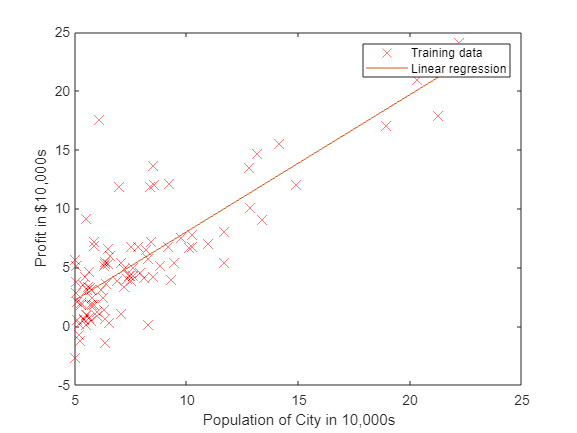


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

J = 3.0870e+06

J = 2.9795e+06

J = 2.8739e+06

J = 2.7703e+06

J = 2.6686e+06

J = 2.5689e+06

J = 2.4712e+06

J = 2.3754e+06

J = 2.2815e+06

J = 2.1896e+06

J = 2.0997e+06

J = 2.0117e+06

J = 1.9257e+06

J = 1.8416e+06

J = 1.7594e+06

J = 1.6793e+06

J = 1.6010e+06

J = 1.5248e+06

J = 1.4505e+06

J = 1.3781e+06

J = 1.3077e+06

J = 1.2392e+06

J = 1.1728e+06

J = 1.1082e+06

J = 1.0456e+06

J = 9.8498e+05

J = 9.2629e+05

J = 8.6956e+05

J = 8.1479e+05

J = 7.6196e+05

J = 7.1109e+05

J = 6.6218e+05

J = 6.1522e+05

J = 5.7021e+05

J = 5.2716e+05

J = 4.8606e+05

J = 4.4691e+05

J = 4.0972e+05

J = 3.7448e+05

J = 3.4119e+05

J = 3.0986e+05

J = 2.8048e+05

J = 2.5306e+05

J = 2.2758e+05

J = 2.0407e+05

J = 1.8250e+05

J = 1.6289e+05

J = 1.4524e+05

J = 1.2954e+05

J = 1.1579e+05

J = 1.0399e+05

J = 9.4151e+04

J = 8.6263e+04

J = 8.0329e+04

J = 7.6349e+04

J = 7.4323e+04

J = 7.4250e+04

J = 7.6131e+04

J = 7.9966e+04

J = 8.5754e+04

J = 9.3496e+04

J = 1.0319e+05

J = 1.1484e+05

J = 1.2844e+05

J = 1.4400e+05

J = 1.6151e+05

J = 1.8098e+05

J = 2.0239e+05

J = 2.2577e+05

J = 2.5109e+05

J = 2.7837e+05

J = 3.0760e+05

J = 3.3879e+05

J = 3.7193e+05

J = 4.0702e+05

J = 4.4407e+05

J = 4.8307e+05

J = 5.2403e+05

J = 5.6694e+05

J = 6.1180e+05

J = 6.5862e+05

J = 7.0739e+05

J = 7.5811e+05

J = 8.1079e+05

J = 8.6542e+05

J = 9.2200e+05

J = 9.8054e+05

J = 1.0410e+06

J = 1.1035e+06

J = 1.1679e+06

J = 1.2342e+06

J = 1.3025e+06

J = 1.3728e+06

J = 1.4450e+06

J = 1.5192e+06

J = 1.5953e+06

J = 1.6734e+06

J = 1.7534e+06

J = 1.8354e+06

J = 1.9193e+06

J = 3.0416e+06

J = 2.9349e+06

J = 2.8301e+06

J = 2.7272e+06

J = 2.6264e+06

J = 2.5274e+06

J = 2.4304e+06

J = 2.3354e+06

J = 2.2424e+06

J = 2.1512e+06

J = 2.0621e+06

J = 1.9749e+06

J = 1.8896e+06

J = 1.8063e+06

J = 1.7250e+06

J = 1.6456e+06

J = 1.5682e+06

J = 1.4927e+06

J = 1.4191e+06

J = 1.3476e+06

J = 1.2779e+06

J = 1.2103e+06

J = 1.1446e+06

J = 1.0808e+06

J = 1.0190e+06

J = 9.5914e+05

J = 9.0123e+05

J = 8.4529e+05

J = 7.9129e+05

J = 7.3926e+05

J = 6.8917e+05

J = 6.4104e+05

J = 5.9486e+05

J = 5.5064e+05

J = 5.0836e+05

J = 4.6805e+05

J = 4.2968e+05

J = 3.9327e+05

J = 3.5882e+05

J = 3.2632e+05

J = 2.9577e+05

J = 2.6717e+05

J = 2.4053e+05

J = 2.1584e+05

J = 1.9311e+05

J = 1.7233e+05

J = 1.5350e+05

J = 1.3663e+05

J = 1.2171e+05

J = 1.0875e+05

J = 9.7734e+04

J = 8.8676e+04

J = 8.1572e+04

J = 7.6421e+04

J = 7.3225e+04

J = 7.1981e+04

J = 7.2692e+04

J = 7.5356e+04

J = 7.9974e+04

J = 8.6546e+04

J = 9.5071e+04

J = 1.0555e+05

J = 1.1798e+05

J = 1.3237e+05

J = 1.4871e+05

J = 1.6700e+05

J = 1.8725e+05

J = 2.0945e+05

J = 2.3361e+05

J = 2.5972e+05

J = 2.8778e+05

J = 3.1780e+05

J = 3.4977e+05

J = 3.8369e+05

J = 4.1957e+05

J = 4.5740e+05

J = 4.9718e+05

J = 5.3892e+05

J = 5.8261e+05

J = 6.2826e+05

J = 6.7586e+05

J = 7.2541e+05

J = 7.7692e+05

J = 8.3038e+05

J = 8.8579e+05

J = 9.4316e+05

J = 1.0025e+06

J = 1.0638e+06

J = 1.1270e+06

J = 1.1922e+06

J = 1.2593e+06

J = 1.3284e+06

J = 1.3994e+06

J = 1.4724e+06

J = 1.5474e+06

J = 1.6243e+06

J = 1.7032e+06

J = 1.7840e+06

J = 1.8667e+06

J = 1.9515e+06

J = 2.9966e+06

J = 2.8906e+06

J = 2.7866e+06

J = 2.6845e+06

J = 2.5844e+06

J = 2.4863e+06

J = 2.3901e+06

J = 2.2959e+06

J = 2.2036e+06

J = 2.1133e+06

J = 2.0249e+06

J = 1.9385e+06

J = 1.8540e+06

J = 1.7715e+06

J = 1.6909e+06

J = 1.6123e+06

J = 1.5356e+06

J = 1.4609e+06

J = 1.3882e+06

J = 1.3174e+06

J = 1.2486e+06

J = 1.1817e+06

J = 1.1168e+06

J = 1.0538e+06

J = 9.9275e+05

J = 9.3368e+05

J = 8.7656e+05

J = 8.2140e+05

J = 7.6819e+05

J = 7.1693e+05

J = 6.6763e+05

J = 6.2028e+05

J = 5.7489e+05

J = 5.3144e+05

J = 4.8996e+05

J = 4.5042e+05

J = 4.1284e+05

J = 3.7722e+05

J = 3.4354e+05

J = 3.1182e+05

J = 2.8206e+05

J = 2.5425e+05

J = 2.2839e+05

J = 2.0449e+05

J = 1.8253e+05

J = 1.6254e+05

J = 1.4450e+05

J = 1.2841e+05

J = 1.1427e+05

J = 1.0209e+05

J = 9.1860e+04

J = 8.3585e+04

J = 7.7264e+04

J = 7.2897e+04

J = 7.0484e+04

J = 7.0024e+04

J = 7.1518e+04

J = 7.4966e+04

J = 8.0367e+04

J = 8.7722e+04

J = 9.7031e+04

J = 1.0829e+05

J = 1.2151e+05

J = 1.3668e+05

J = 1.5380e+05

J = 1.7288e+05

J = 1.9391e+05

J = 2.1690e+05

J = 2.4183e+05

J = 2.6873e+05

J = 2.9757e+05

J = 3.2837e+05

J = 3.6112e+05

J = 3.9583e+05

J = 4.3249e+05

J = 4.7111e+05

J = 5.1167e+05

J = 5.5420e+05

J = 5.9867e+05

J = 6.4510e+05

J = 6.9348e+05

J = 7.4382e+05

J = 7.9611e+05

J = 8.5035e+05

J = 9.0655e+05

J = 9.6470e+05

J = 1.0248e+06

J = 1.0869e+06

J = 1.1509e+06

J = 1.2168e+06

J = 1.2848e+06

J = 1.3546e+06

J = 1.4265e+06

J = 1.5002e+06

J = 1.5760e+06

J = 1.6537e+06

J = 1.7333e+06

J = 1.8149e+06

J = 1.8985e+06

J = 1.9840e+06

J = 2.9519e+06

J = 2.8467e+06

J = 2.7435e+06

J = 2.6422e+06

J = 2.5429e+06

J = 2.4456e+06

J = 2.3501e+06

J = 2.2567e+06

J = 2.1652e+06

J = 2.0756e+06

J = 1.9881e+06

J = 1.9024e+06

J = 1.8187e+06

J = 1.7370e+06

J = 1.6572e+06

J = 1.5794e+06

J = 1.5035e+06

J = 1.4296e+06

J = 1.3576e+06

J = 1.2876e+06

J = 1.2196e+06

J = 1.1535e+06

J = 1.0893e+06

J = 1.0271e+06

J = 9.6689e+05

J = 9.0860e+05

J = 8.5227e+05

J = 7.9789e+05

J = 7.4546e+05

J = 6.9499e+05

J = 6.4647e+05

J = 5.9991e+05

J = 5.5529e+05

J = 5.1264e+05

J = 4.7193e+05

J = 4.3318e+05

J = 3.9639e+05

J = 3.6154e+05

J = 3.2865e+05

J = 2.9772e+05

J = 2.6874e+05

J = 2.4171e+05

J = 2.1663e+05

J = 1.9351e+05

J = 1.7234e+05

J = 1.5313e+05

J = 1.3587e+05

J = 1.2057e+05

J = 1.0721e+05

J = 9.5815e+04

J = 8.6370e+04

J = 7.8878e+04

J = 7.3341e+04

J = 6.9757e+04

J = 6.8127e+04

J = 6.8451e+04

J = 7.0728e+04

J = 7.4959e+04

J = 8.1144e+04

J = 8.9282e+04

J = 9.9374e+04

J = 1.1142e+05

J = 1.2542e+05

J = 1.4137e+05

J = 1.5928e+05

J = 1.7914e+05

J = 2.0095e+05

J = 2.2472e+05

J = 2.5044e+05

J = 2.7812e+05

J = 3.0775e+05

J = 3.3933e+05

J = 3.7287e+05

J = 4.0836e+05

J = 4.4580e+05

J = 4.8520e+05

J = 5.2655e+05

J = 5.6986e+05

J = 6.1512e+05

J = 6.6233e+05

J = 7.1149e+05

J = 7.6261e+05

J = 8.1569e+05

J = 8.7071e+05

J = 9.2770e+05

J = 9.8663e+05

J = 1.0475e+06

J = 1.1104e+06

J = 1.1752e+06

J = 1.2419e+06

J = 1.3106e+06

J = 1.3813e+06

J = 1.4539e+06

J = 1.5284e+06

J = 1.6050e+06

J = 1.6834e+06

J = 1.7639e+06

J = 1.8462e+06

J = 1.9306e+06

J = 2.0169e+06

J = 2.9076e+06

J = 2.8032e+06

J = 2.7008e+06

J = 2.6003e+06

J = 2.5018e+06

J = 2.4052e+06

J = 2.3106e+06

J = 2.2179e+06

J = 2.1272e+06

J = 2.0384e+06

J = 1.9516e+06

J = 1.8668e+06

J = 1.7839e+06

J = 1.7029e+06

J = 1.6239e+06

J = 1.5469e+06

J = 1.4718e+06

J = 1.3987e+06

J = 1.3275e+06

J = 1.2582e+06

J = 1.1910e+06

J = 1.1257e+06

J = 1.0623e+06

J = 1.0009e+06

J = 9.4142e+05

J = 8.8391e+05

J = 8.2836e+05

J = 7.7477e+05

J = 7.2312e+05

J = 6.7343e+05

J = 6.2570e+05

J = 5.7992e+05

J = 5.3609e+05

J = 4.9421e+05

J = 4.5429e+05

J = 4.1633e+05

J = 3.8031e+05

J = 3.4625e+05

J = 3.1415e+05

J = 2.8399e+05

J = 2.5580e+05

J = 2.2955e+05

J = 2.0526e+05

J = 1.8292e+05

J = 1.6254e+05

J = 1.4411e+05

J = 1.2763e+05

J = 1.1311e+05

J = 1.0054e+05

J = 8.9925e+04

J = 8.1263e+04

J = 7.4556e+04

J = 6.9801e+04

J = 6.7001e+04

J = 6.6154e+04

J = 6.7261e+04

J = 7.0322e+04

J = 7.5336e+04

J = 8.2304e+04

J = 9.1226e+04

J = 1.0210e+05

J = 1.1493e+05

J = 1.2971e+05

J = 1.4645e+05

J = 1.6514e+05

J = 1.8578e+05

J = 2.0838e+05

J = 2.3293e+05

J = 2.5944e+05

J = 2.8790e+05

J = 3.1831e+05

J = 3.5068e+05

J = 3.8500e+05

J = 4.2127e+05

J = 4.5950e+05

J = 4.9968e+05

J = 5.4181e+05

J = 5.8590e+05

J = 6.3194e+05

J = 6.7994e+05

J = 7.2989e+05

J = 7.8179e+05

J = 8.3565e+05

J = 8.9146e+05

J = 9.4922e+05

J = 1.0089e+06

J = 1.0706e+06

J = 1.1342e+06

J = 1.1998e+06

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

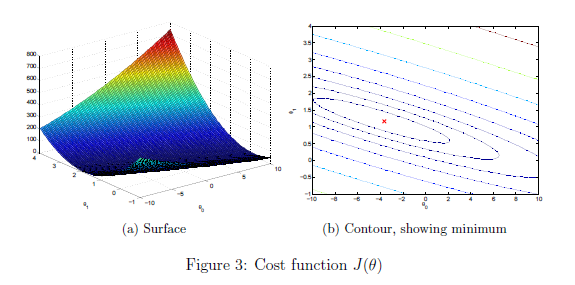

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

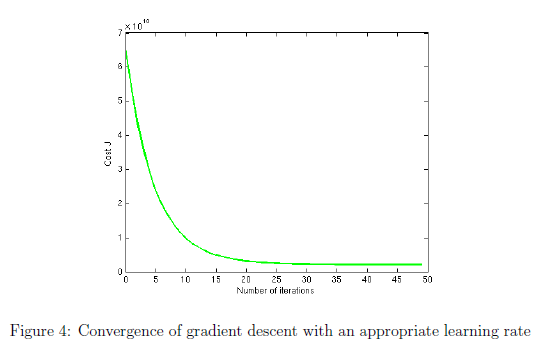

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

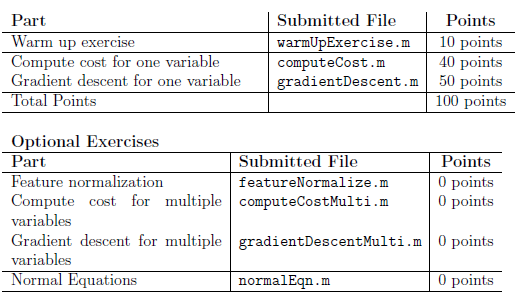

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.